# 求解方程与方程组

## 求解简单方程

syms x
answ = solve(sin(x) == 1, x)

$$answ = \frac{\pi }{2}$$

## 获得周期函数所有解

syms x
eqn = (sin(x) == 1);
% answ = solve(eqn, x)
[answ, params, conditions] = solve(eqn, x, "ReturnConditions",true)

$$answ = \frac{\pi }{2}+2\,\pi \,k$$

$$params = k$$

$$conditions = k\in \mathbb{Z}$$

## 求解方程组

syms u v a
eqn = [2*u + v == a, u - v == 1];
answ = solve(eqn, [u, v]);
answ

answ = 包含以下字段的 struct :
    u: [1×1 sym]
    v: [1×1 sym]


answ.u, answ.v

$$ans = \frac{a}{3}+\frac{1}{3}$$

$$ans = \frac{a}{3}-\frac{2}{3}$$

## vpasolve 求解函数(数值解)

syms x y
eqn = [x^2-2*x-3*x*y == 10, y^4 == exp(-2*x/3)] % Matlab对空格敏感(可用于分割数组)

$$eqn = \left(\begin{array}{cc} x^{2}-3\,x\,y-2\,x=10 & y^{4}={\mathrm{e}}^{-\frac{2\,x}{3}} \end{array}\right)$$

answ = vpasolve(eqn, [x,y], [0, 0])

answ = 包含以下字段的 struct :
    x: [1×1 sym]
    y: [1×1 sym]


answ.x, answ.y

$$ans = -1.393259627845404026653388391876$$

$$ans = 1.261384513542676943005039668231$$

answ2 = vpasolve(eqn, [x,y],'Random',true)

answ2 = 包含以下字段的 struct :
    x: [1×1 sym]
    y: [1×1 sym]


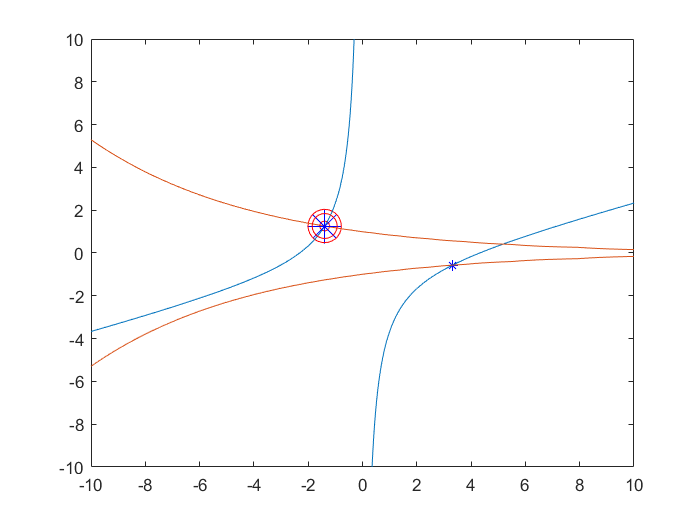

% 作图
fimplicit(x^2-2*x-3*x*y == 10, [-10, 10]);
hold on;
fimplicit(y^4 == exp(-2*x/3), [-10, 10])
hold on
plot(answ.x, answ.y, 'ro','MarkerSize', 15);
hold on;
plot(answ2.x, answ2.y, 'b*', 'MarkerSize',10);

## fsolve 函数求解

answ3 = fsolve(@myfun, [0, 0]);


No solution found.

fsolve stopped because the problem appears regular as measured by the gradient,
but the vector of function values is not near zero as measured by the
value of the function tolerance.

<stopping criteria details>


answ3

answ3 =          0    0.6686


function myF = myfun(X)
    myF(1) = X(1)^2 + 2 - sqrt(X(2)^3);
    myF(2) = X(1)^3 - exp(X(2)^4);
end